% Parameters
fs = 8;                 % Sampling frequency (Hz)
T  = 1/fs;              % Sampling period
N  = 5                  % N

N = 5

t  = 0:0.001:1;         % High-res time vector for continuous signals

% Signals
x1 = cos(2*pi*5*t);    % x1(t) = cos(2π·5t)
x2 = cos(2*pi*3*t);    % x2(t) = cos(2π·3t)

[t1_s, x1_s] = sample_signal(t, x1, fs);
[t2_s, x2_s] = sample_signal(t, x2, fs);

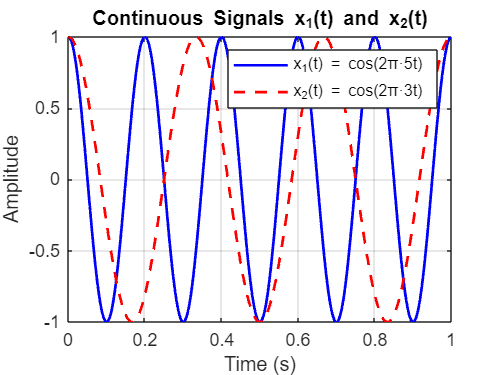

%% Plot continuous and sampled signals
figure;
plot(t, x1, 'b', 'LineWidth', 1.5); hold on;
plot(t, x2, 'r--', 'LineWidth', 1.5);
legend('x_1(t) = cos(2π·5t)', 'x_2(t) = cos(2π·3t)');
xlabel('Time (s)'); ylabel('Amplitude');
title('Continuous Signals x_1(t) and x_2(t)');
grid on;

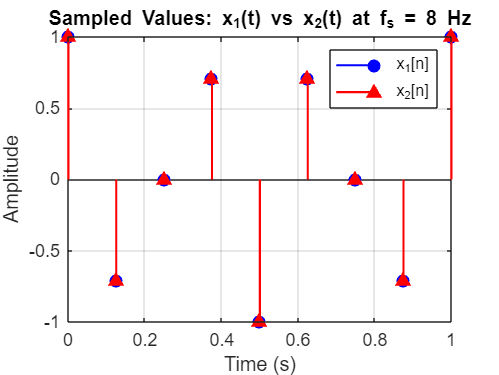

%% Plot sampled signal comparison
figure;
stem(t1_s, x1_s, 'bo', 'filled', 'LineWidth', 1.2); hold on;
stem(t2_s, x2_s, 'r^', 'filled', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Sampled Values: x_1(t) vs x_2(t) at f_s = 8 Hz');
legend('x_1[n]', 'x_2[n]');
grid on;

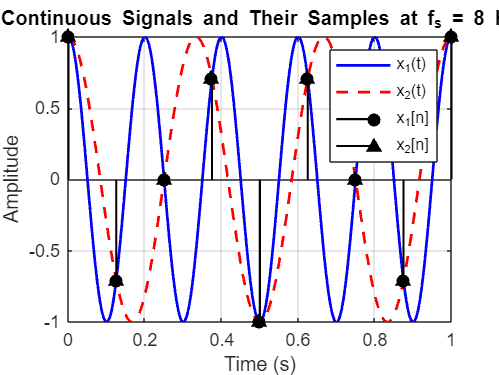

% Plot
figure;
plot(t, x1, 'b-', 'LineWidth', 1.5); hold on;
plot(t, x2, 'r--', 'LineWidth', 1.5);
stem(t1_s, x1_s, 'ko', 'filled', 'LineWidth', 1.2);   % black circles
stem(t2_s, x2_s, 'k^', 'filled', 'LineWidth', 1.2);   % black triangles
xlabel('Time (s)');
ylabel('Amplitude');
title('Continuous Signals and Their Samples at f_s = 8 Hz');
legend('x_1(t)', 'x_2(t)','x_1[n]', 'x_2[n]');
grid on;

% Frequency domain visualization

Fs = 50; % high sampling rate for accurate FFT
t_f = 0:1/Fs:1; 
x1_f = cos(2*pi*5*t_f); 
x2_f = cos(2*pi*3*t_f);

nfft = 1024;
X1 = abs(fftshift(fft(x1_f, nfft)));
X2 = abs(fftshift(fft(x2_f, nfft)));
f = linspace(-Fs/2, Fs/2, nfft);

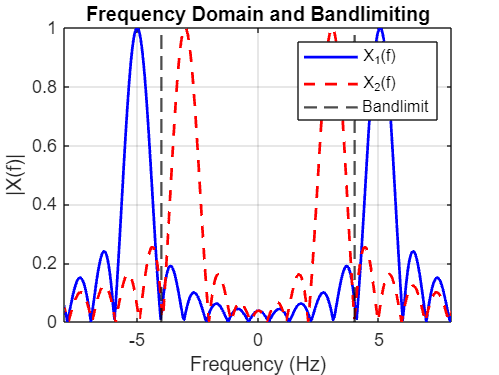

% Plot
figure;
plot(f, X1/max(X1), 'b', 'LineWidth', 1.5); hold on;
plot(f, X2/max(X2), 'r--', 'LineWidth', 1.5);
xline(4, 'k--', 'LineWidth', 1.2);
xline(-4, 'k--', 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Frequency Domain and Bandlimiting');
legend('X_1(f)', 'X_2(f)', 'Bandlimit');
grid on;
xlim([-8 8])

%% Continuous vs Sampled signals at fs = 9 Hz
fs_new = 9;
T_new = 1/fs_new;
t_new = 0:0.001:1;              % Continuous time for plotting
n_new = 0:T_new:1;              % Discrete sample times

x1_cont = cos(2*pi*5*t_new);    % Continuous x1
x2_cont = cos(2*pi*3*t_new);    % Continuous x2
x1_samp = cos(2*pi*5*n_new);    % Sampled x1
x2_samp = cos(2*pi*3*n_new);    % Sampled x2

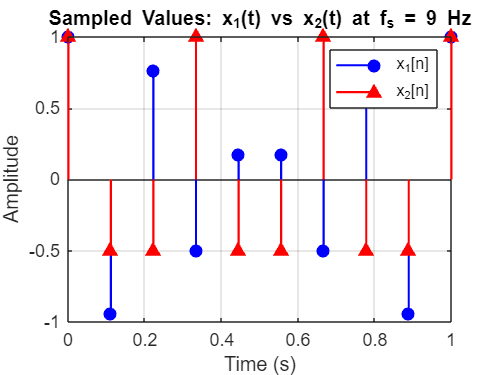

%% Plot sampled signal comparison
figure;
stem(n_new, x1_samp, 'bo', 'filled', 'LineWidth', 1.2); hold on;
stem(n_new, x2_samp, 'r^', 'filled', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Sampled Values: x_1(t) vs x_2(t) at f_s = 9 Hz');
legend('x_1[n]', 'x_2[n]');
grid on;

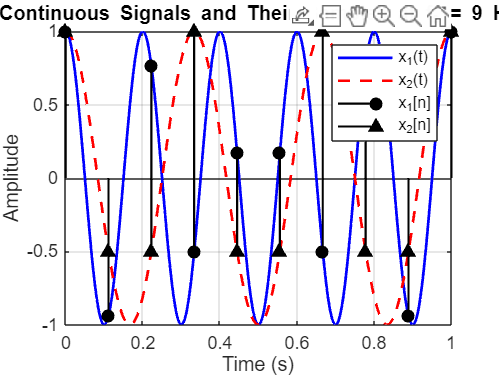

% Plot
figure;
plot(t_new, x1_cont, 'b-', 'LineWidth', 1.5); hold on;
plot(t_new, x2_cont, 'r--', 'LineWidth', 1.5);
stem(n_new, x1_samp, 'ko', 'filled', 'LineWidth', 1.2);   % black circles
stem(n_new, x2_samp, 'k^', 'filled', 'LineWidth', 1.2);   % black triangles
xlabel('Time (s)');
ylabel('Amplitude');
title('Continuous Signals and Their Samples at f_s = 9 Hz');
legend('x_1(t)', 'x_2(t)','x_1[n]', 'x_2[n]');
grid on;